# Característiques locals III

## Detector de Harris

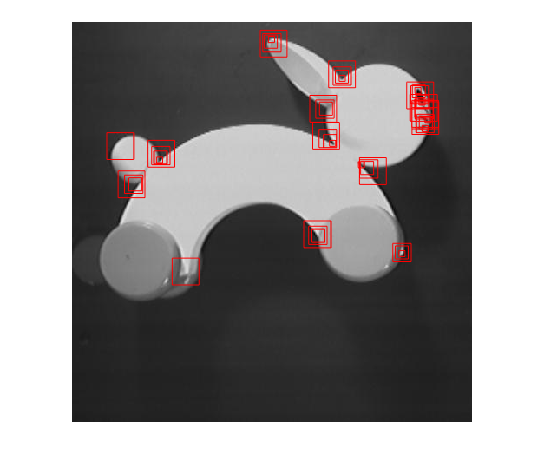

BW = imread("rabbit.jpg");
imshow(BW);
sizes = [7 15 21 31];
hold on
for j = 1:size(sizes,2)
    wsize = sizes(j);
    keyPoints = detectHarrisFeatures(BW,'FilterSize',wsize,'MinQuality',0.1);
    for i = 1:size(keyPoints,1)
        rectangle('Position',[keyPoints.Location(i,1)-wsize/2, keyPoints.Location(i,2)-wsize/2, wsize, wsize],'EdgeColor','r');
    end
end

## Detector de Min Eigen

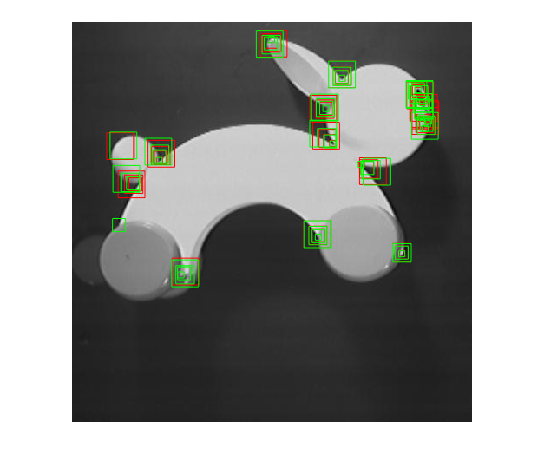

BW = imread("rabbit.jpg");
sizes = [7 15 21 31];
for j = 1:size(sizes,2)
    wsize = sizes(j);
    keyPoints = detectMinEigenFeatures(BW,'FilterSize',wsize,'MinQuality',0.15);
    for i = 1:size(keyPoints,1)
        rectangle('Position',[keyPoints.Location(i,1)-wsize/2, keyPoints.Location(i,2)-wsize/2, wsize, wsize],'EdgeColor','g');
    end
end

## Detector de FAST

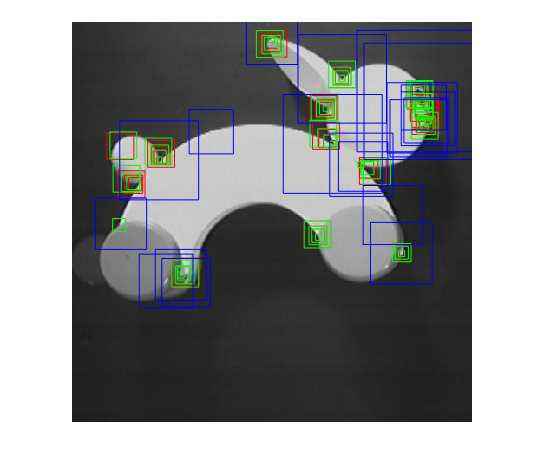

BW = imread("rabbit.jpg");
keyPoints = detectFASTFeatures(BW,'MinQuality',0.15);
for i = 1:size(keyPoints,1)
    wsize = keyPoints.Metric(i);
    rectangle('Position',[keyPoints.Location(i,1)-wsize/2, keyPoints.Location(i,2)-wsize/2, wsize, wsize],'EdgeColor','b');
end
hold off

## Diferència de filtres gaussians

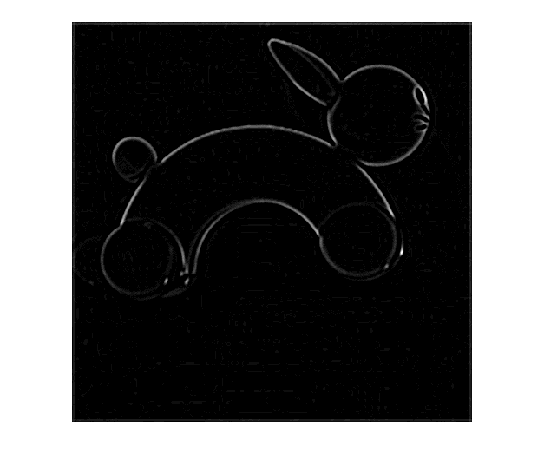

im = imread('rabbit.jpg');
h = fspecial('gaussian',7,7/4);
G1 = imfilter(im,h);
h2 = fspecial('gaussian',9,9/4);
G2 = imfilter(im,h2);
imshow(G1-G2,[]);

## Detecctió per STIF i RANSAC

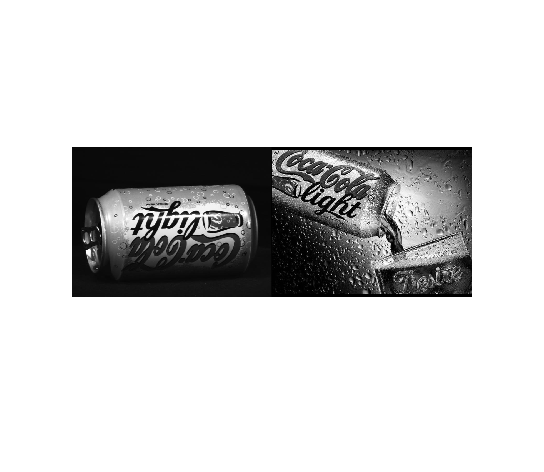

im_obj = rgb2gray(imread('coke.jpg'));
im_esc = rgb2gray(imread('anunci.jpg'));
montage({im_obj,im_esc});

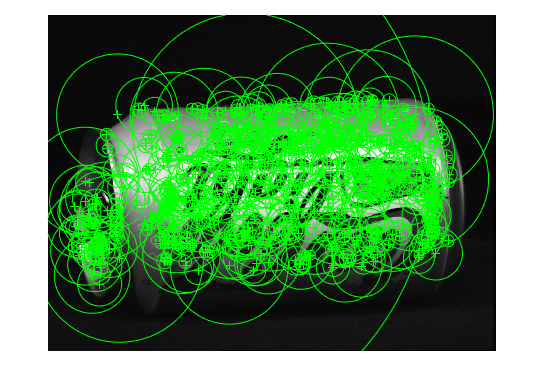

kp_obj = detectSIFTFeatures(im_obj);
kp_esc = detectSIFTFeatures(im_esc);
%kp_obj = selectStrongest(kp_obj,50);
%kp_esc = selectStrongest(kp_esc,300);
figure, imshow(im_obj);
hold on
plot(kp_obj);
hold off

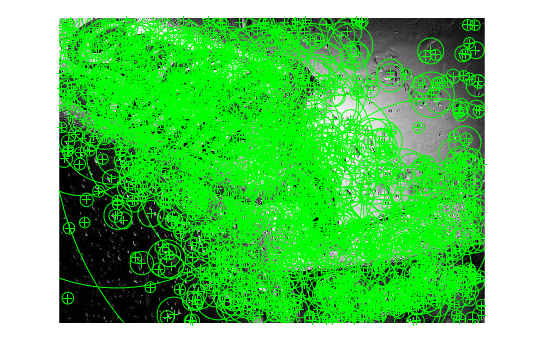

figure, imshow(im_esc);
hold on
plot(kp_esc);
hold off

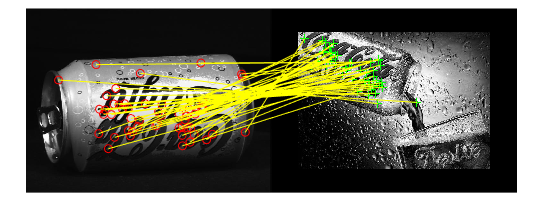


[feat_obj, kp_obj] = extractFeatures(im_obj,kp_obj);
[feat_esc, kp_esc] = extractFeatures(im_esc,kp_esc);

pairs = matchFeatures(feat_obj,feat_esc,'MatchThreshold',10);
best_kp_obj = kp_obj(pairs(:,1),:);
best_kp_esc = kp_esc(pairs(:,2),:);

figure
showMatchedFeatures(im_obj,im_esc,best_kp_obj,best_kp_esc,'montage');

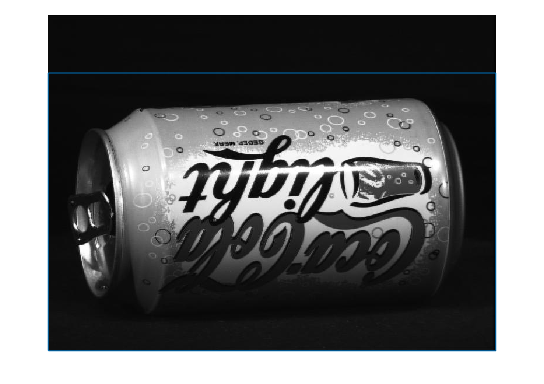


[T] = estimateGeometricTransform2D(best_kp_obj,best_kp_esc,'affine');
[fo,co] = size(im_obj);
[fe,ce] = size(im_esc);
box = [1,100;co,100;co,fo;1,fo;1,100];
figure, imshow(im_obj);
hold on
line(box(:,1),box(:,2));

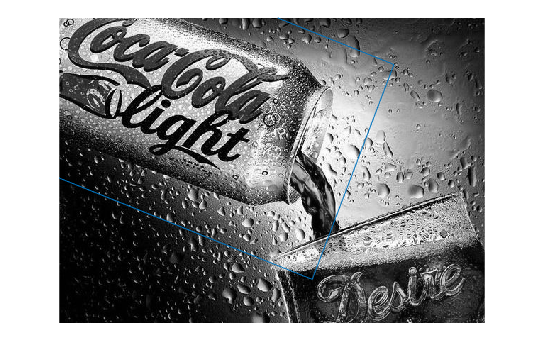


nbox = transformPointsForward(T,box);
figure, imshow(im_esc);
hold on
line(nbox(:,1),nbox(:,2));

## Exercici STIF i RANSAC

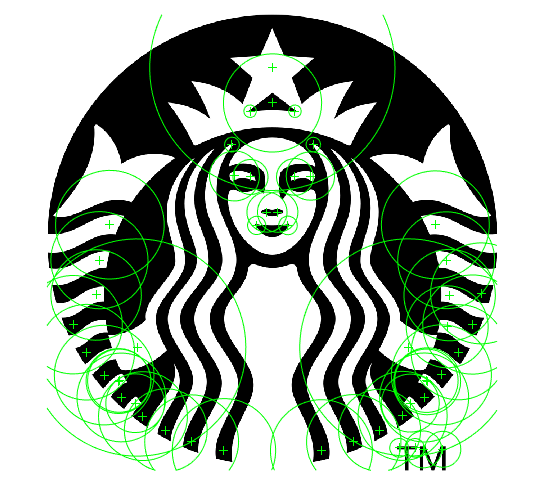

im_obj = im2gray(imread('starbucks_logo.png'));
im_esc = im2gray(imread('starbucks_cup4.jpeg'));

%montage({im_obj,im_esc});
kp_obj = detectSIFTFeatures(im_obj);
kp_esc = detectSIFTFeatures(im_esc);
kp_obj = selectStrongest(kp_obj,50);
kp_esc = selectStrongest(kp_esc,1000);
figure, imshow(im_obj,[]);
hold on
plot(kp_obj);
hold off

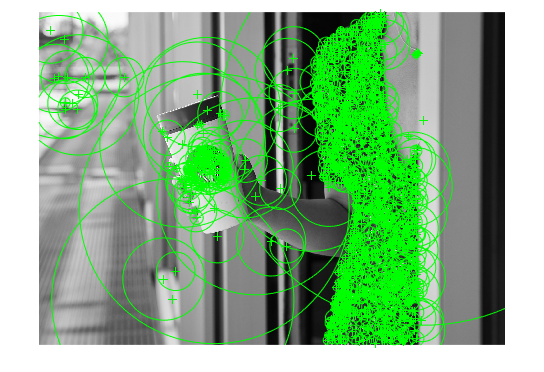

figure, imshow(im_esc,[]);
hold on
plot(kp_esc);
hold off

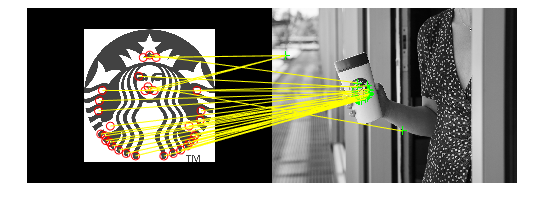


[feat_obj, kp_obj] = extractFeatures(im_obj,kp_obj);
[feat_esc, kp_esc] = extractFeatures(im_esc,kp_esc);

pairs = matchFeatures(feat_obj,feat_esc,'MatchThreshold',10);
best_kp_obj = kp_obj(pairs(:,1),:);
best_kp_esc = kp_esc(pairs(:,2),:);

figure
showMatchedFeatures(im_obj,im_esc,best_kp_obj,best_kp_esc,'montage');

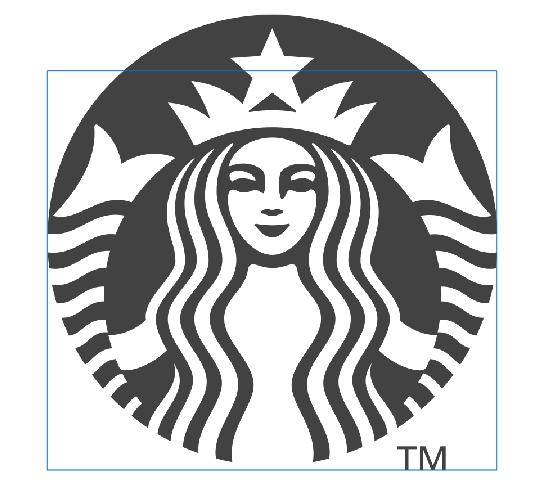


[T] = estimateGeometricTransform2D(best_kp_obj,best_kp_esc,'affine');
[fo,co] = size(im_obj);
[fe,ce] = size(im_esc);
box = [1,100;co,100;co,fo;1,fo;1,100];
figure, imshow(im_obj);
hold on
line(box(:,1),box(:,2));

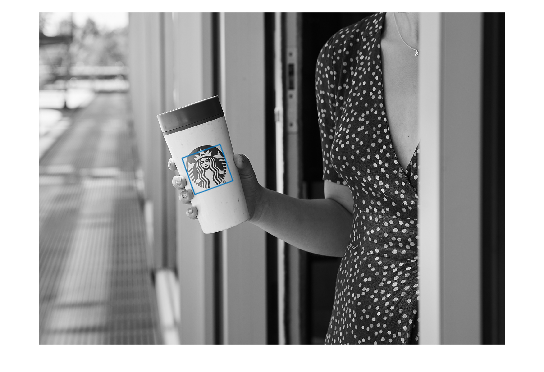


nbox = transformPointsForward(T,box);
figure, imshow(im_esc);
hold on
line(nbox(:,1),nbox(:,2));